## BIV-Übung 2

Hadi Saleh 1822230

### 3  Punkt-Operatoren: Ausschneiden und einsetzen

a)

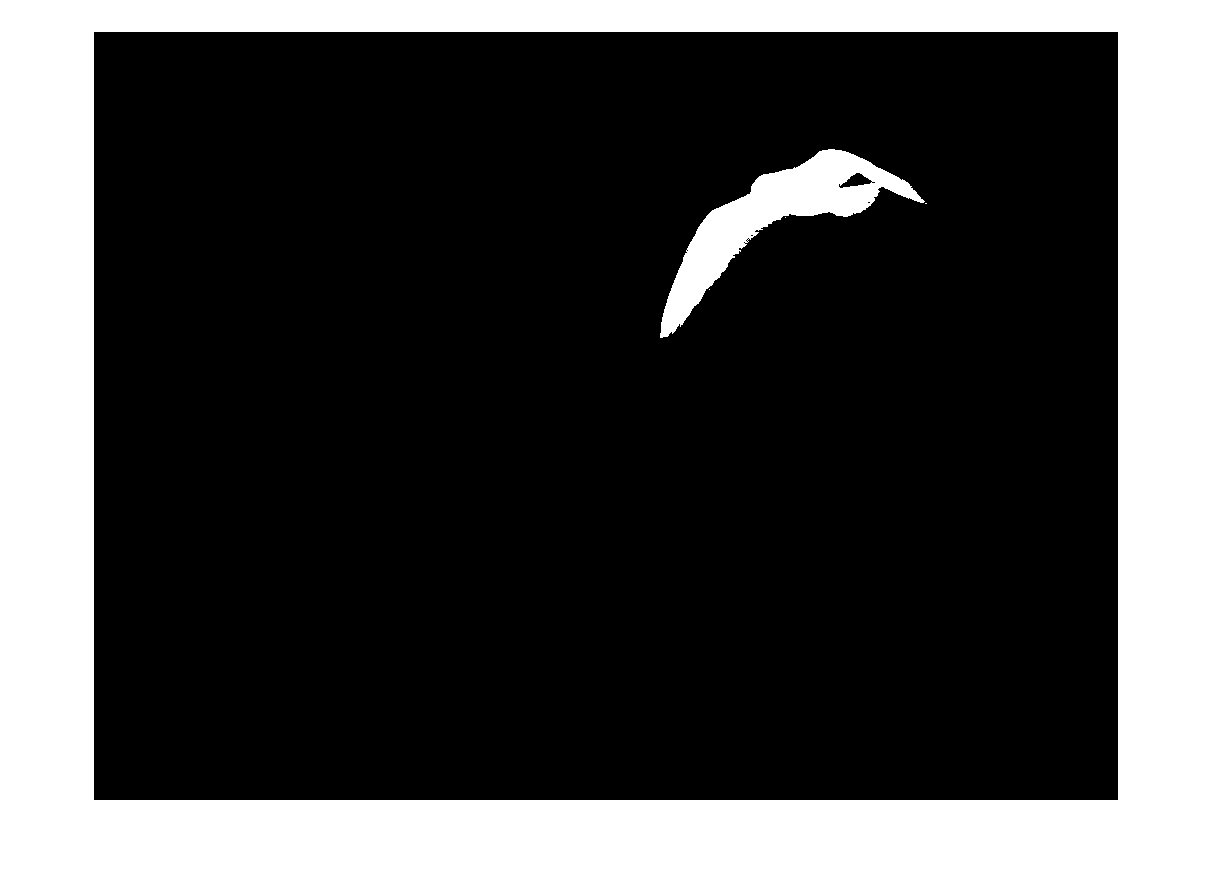

moewe=imread('moewex.jpg');
red = moewe(:, :, 1);
green = moewe(:, :, 2);
blue = moewe(:, :, 3);
cut_moewe = 1 - ((blue > 150) .* (red < 150));
figure
imshow(cut_moewe)

b)

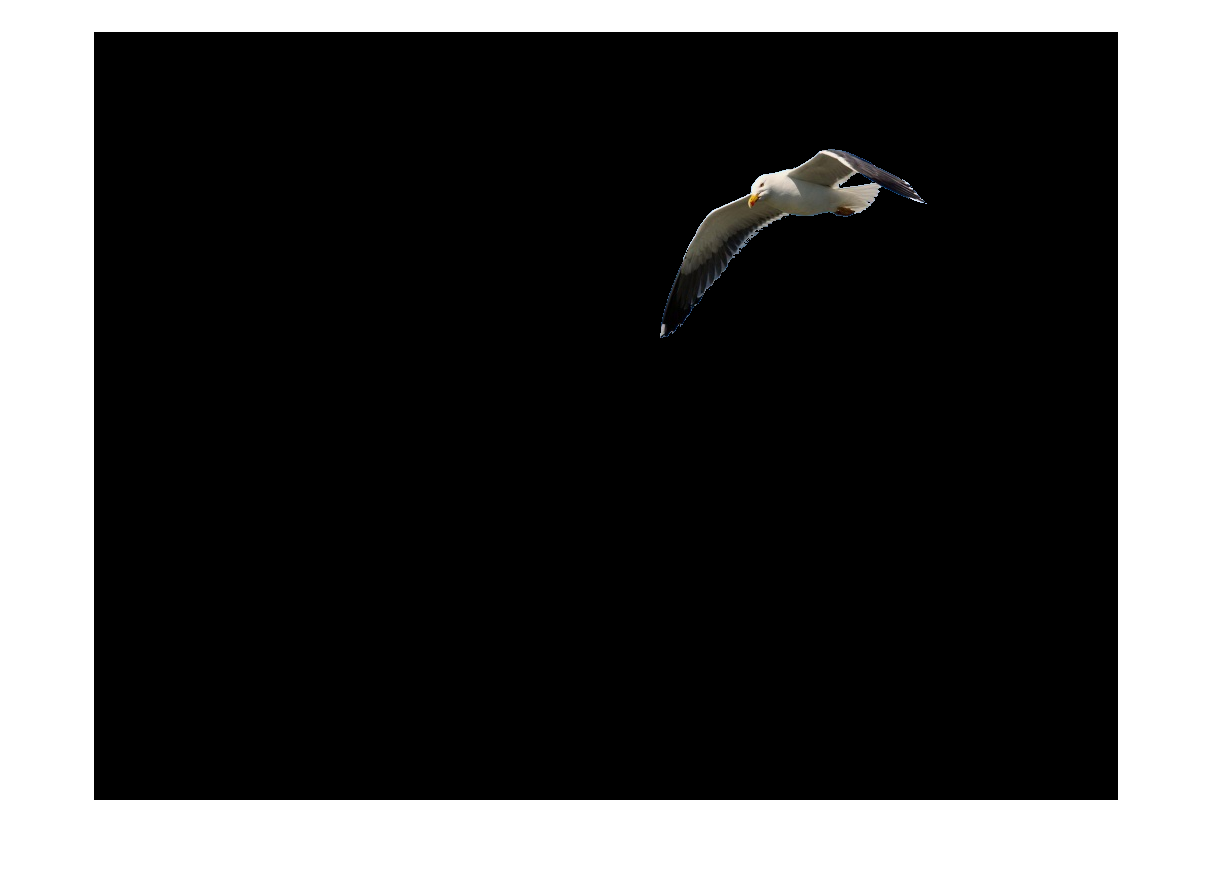

cut_moewe_rgb = uint8(repmat(cut_moewe, [1 1 3]));
moewe_cutout = cut_moewe_rgb .* moewe;
imshow(moewe_cutout)

c)

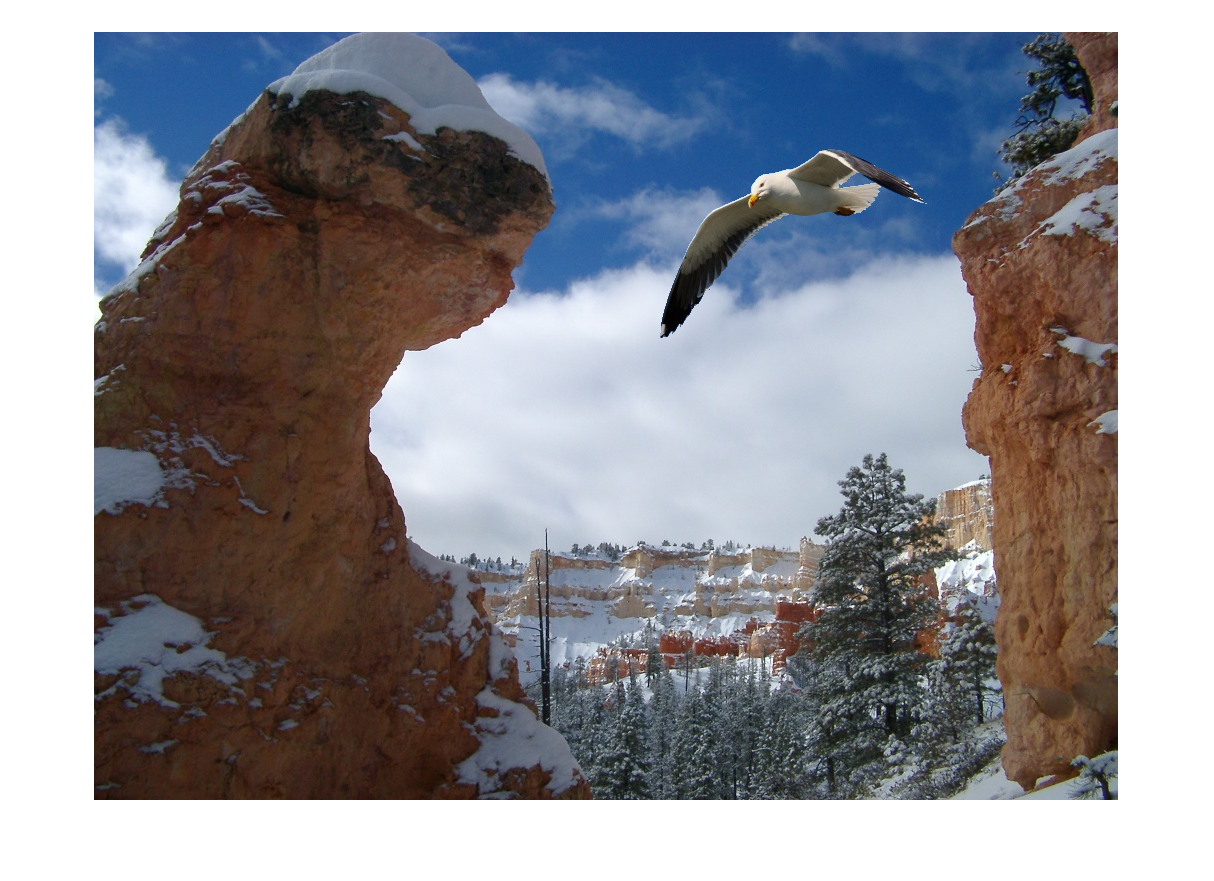

bryce = imread('bryce.jpg');
bryce_with_hole = (1 - cut_moewe_rgb) .* bryce;
bryce_with_moewe = bryce_with_hole + moewe_cutout;
imshow(bryce_with_moewe)